a = 0: Jacobian at origin = [0 -1; 1 0], eigenvalues = ± i


  Expect center (closed orbits).


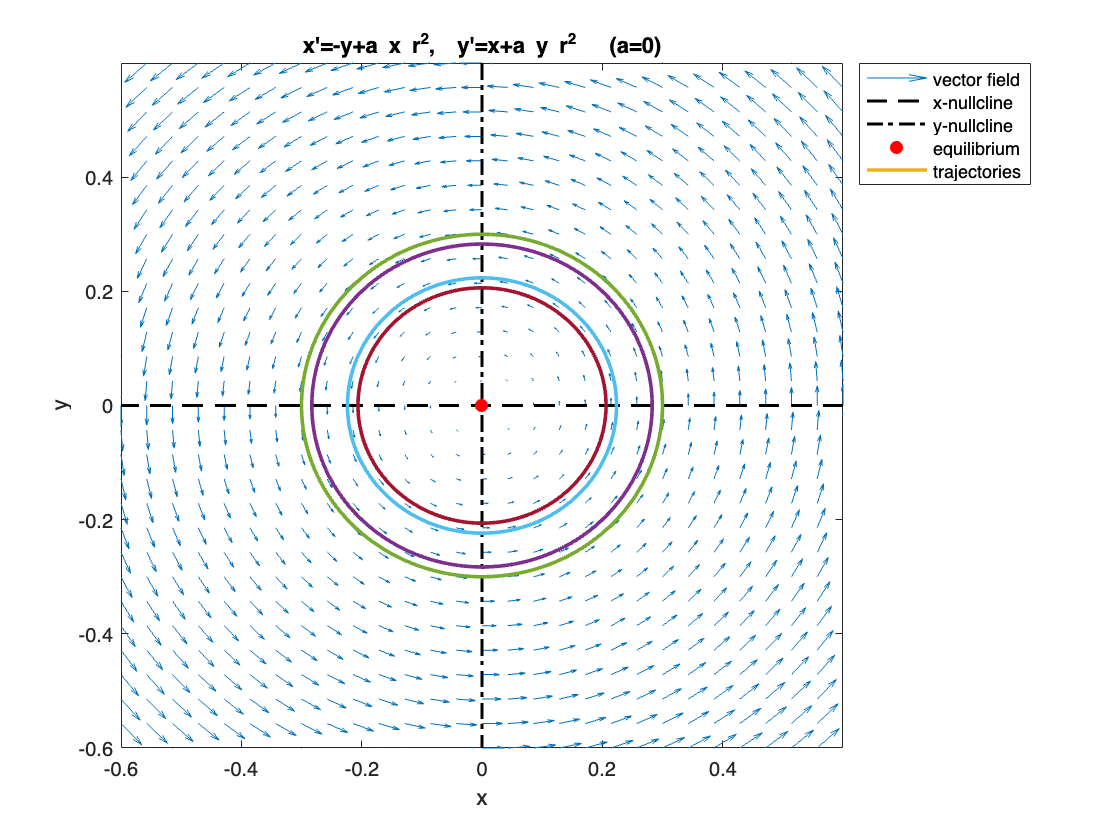

a = 0.5: Jacobian at origin = [0 -1; 1 0], eigenvalues = ± i


  Expect unstable focus (spiral out), since r' = a r^3 > 0.


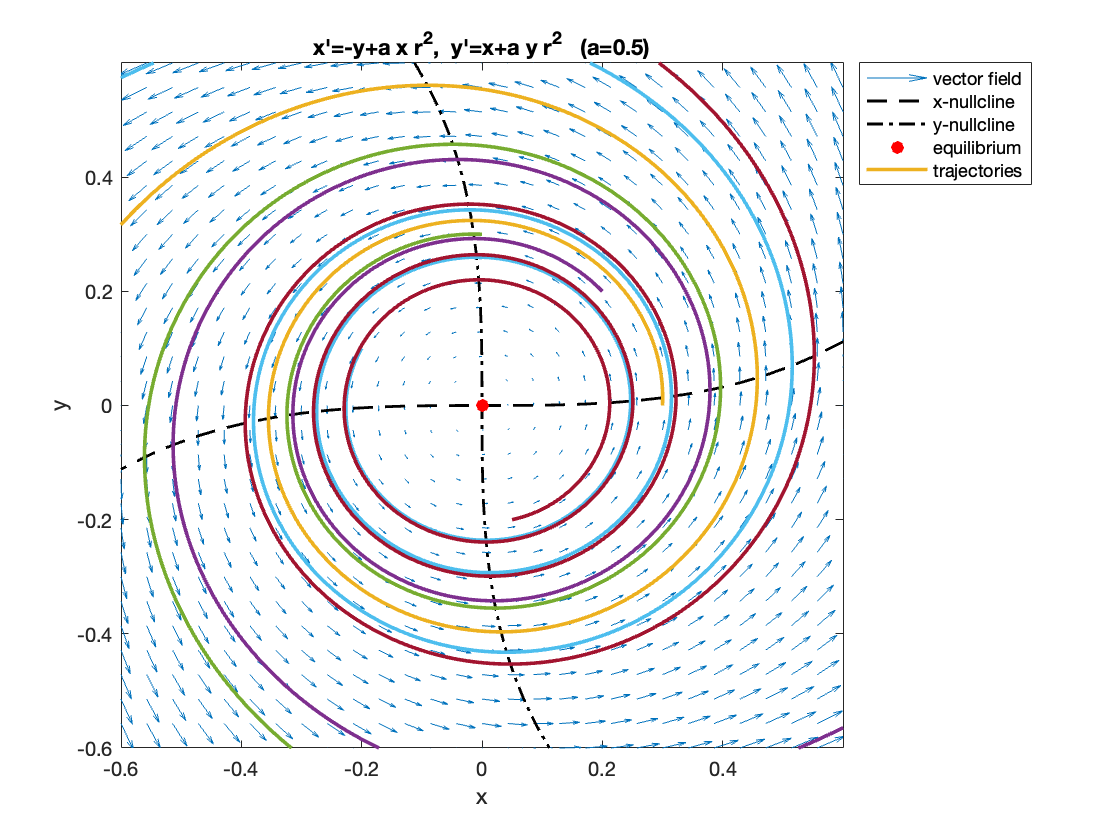

a = -0.5: Jacobian at origin = [0 -1; 1 0], eigenvalues = ± i


  Expect stable focus (spiral in), since r' = a r^3 < 0.


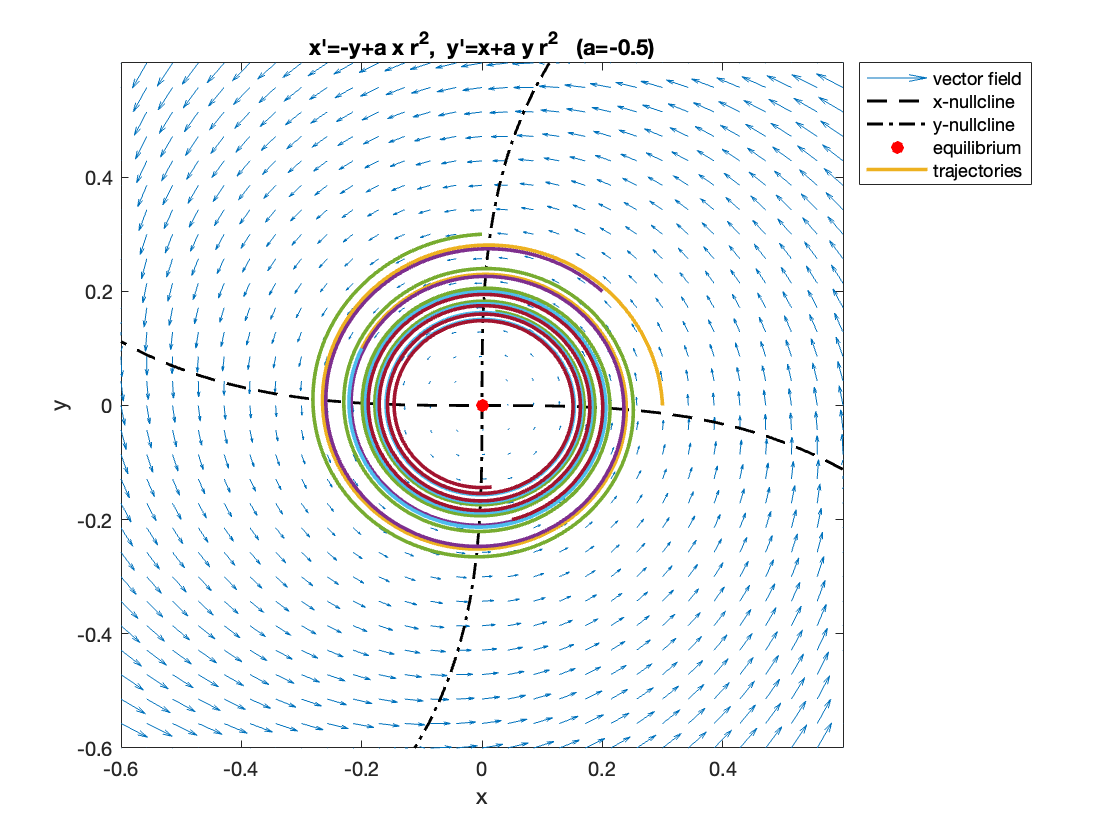

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% System (in R^2):
%   x' = -y + a x (x^2 + y^2)
%   y' =  x + a y (x^2 + y^2)
%
% Goal:
%   - Compare cases a=0 (center), a<0 (spiral sink), a>0 (spiral source)
%   - phase portrait: vector field + nullclines + trajectories
%   - local linearization at origin
%
% Key analytic fact (polar coordinates):
%   Let r^2 = x^2+y^2. Then
%     r'     = a r^3
%     theta' = 1
%   So:
%     a=0: r'=0 -> closed circles (true center)
%     a<0: r decreases -> spiral in (stable focus)
%     a>0: r increases -> spiral out (unstable focus), finite-time blow-up possible
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

a_list = [0, 0.5, -0.5];  % demo three cases

% Plot window
xlimv = [-0.6 0.6];
ylimv = [-0.6 0.6];

% Initial conditions (avoid too large radii if a>0 to prevent blow-up quickly)
ICs = [ 0.3 0.0;
        0.2 0.2;
        0.0 0.3;
       -0.2 0.1;
        0.05 -0.2];

tspan = [0 25];

for ai = 1:numel(a_list)
    a = a_list(ai);

    f = @(t,z) [ -z(2) + a*z(1)*(z(1)^2+z(2)^2);
                  z(1) + a*z(2)*(z(1)^2+z(2)^2) ];

    % Jacobian at (0,0): [[0,-1],[1,0]] independent of a
    J0 = [0 -1; 1 0];
    lam0 = eig(J0);

    fprintf('a = %.3g: Jacobian at origin = [0 -1; 1 0], eigenvalues = ± i\n', a);
    if a==0
        fprintf('  Expect center (closed orbits).\n');
    elseif a>0
        fprintf('  Expect unstable focus (spiral out), since r'' = a r^3 > 0.\n');
    else
        fprintf('  Expect stable focus (spiral in), since r'' = a r^3 < 0.\n');
    end

    % Grid for vector field
    [xg,yg] = meshgrid(linspace(xlimv(1),xlimv(2),29), linspace(ylimv(1),ylimv(2),29));
    ug = -yg + a*xg.*(xg.^2+yg.^2);
    vg =  xg + a*yg.*(xg.^2+yg.^2);

    figure('Color','w','Name',sprintf('Example 2: a=%.2g',a));
    hold on; box on;
    quiver(xg,yg,ug,vg,'AutoScale','on');
    xlabel('x'); ylabel('y');
    title(sprintf('x''=-y+a x r^2,  y''=x+a y r^2   (a=%.2g)', a));

    % Nullclines via contour (robust: no fimplicit needed)
    % x-nullcline: -y + a x (x^2+y^2) = 0
    % y-nullcline:  x + a y (x^2+y^2) = 0
    plot_nullcline_contour(xg,yg, -yg + a*xg.*(xg.^2+yg.^2), 'k--'); % x'=0
    plot_nullcline_contour(xg,yg,  xg + a*yg.*(xg.^2+yg.^2), 'k-.'); % y'=0

    % Equilibrium (only origin)
    plot(0,0,'ro','MarkerFaceColor','r','MarkerSize',6);

    % Trajectories
    for k = 1:size(ICs,1)
        z0 = ICs(k,:)';
        % If a>0, trajectories may blow up. Use event to stop if |z| too big.
        opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'Events',@(t,z) stop_if_radius_big(t,z,10));
        [t,z] = ode45(f, tspan, z0, opts);
        plot(z(:,1),z(:,2),'LineWidth',1.8);
    end

    xlim(xlimv); ylim(ylimv);
    legend({'vector field','x-nullcline','y-nullcline','equilibrium','trajectories'}, ...
        'Location','bestoutside');

    % Quick note to say aloud in class:
    % The direction of spiraling is counterclockwise because theta' = 1.
end